A = [1 2; 3 4];
B = [1;1];
C = [1 1];
G1 = ss(A,B,C,0);
[num,den]=ss2tf(A,B,C,D);
G = tf(num,den)

G =
 
  2 s - 8.882e-16
  ---------------
   s^2 - 5 s - 2
 
Continuous-time transfer function.



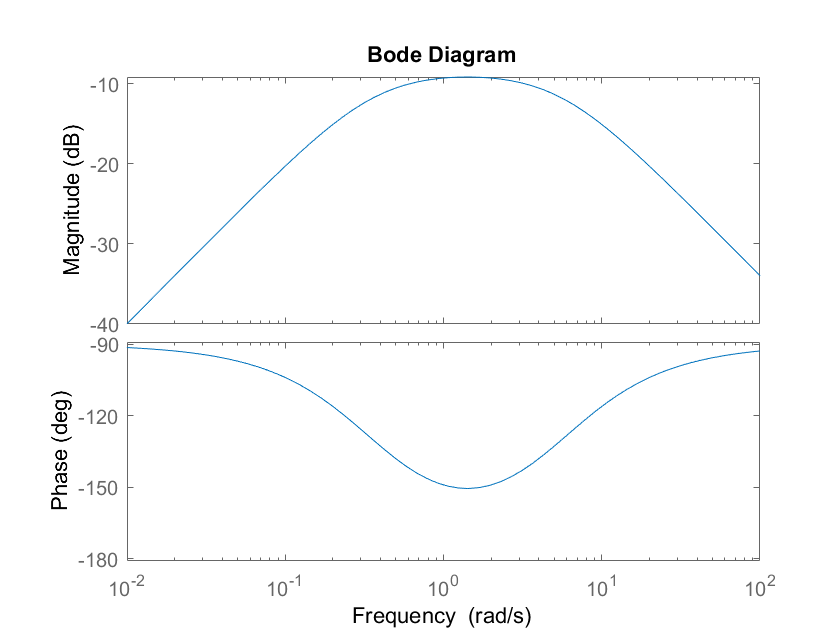

bode(G)

s = tf('s');
G2 = C *inv(s * eye(2) - A) * B

G2 =
 
  2 s^7 - 30 s^6 + 138 s^5 - 130 s^4 - 276 s^3 - 120 s^2 - 16 s + 2.292e-13
  --------------------------------------------------------------------------
  s^8 - 20 s^7 + 142 s^6 - 380 s^5 + 49 s^4 + 760 s^3 + 568 s^2 + 160 s + 16
 
Continuous-time transfer function.



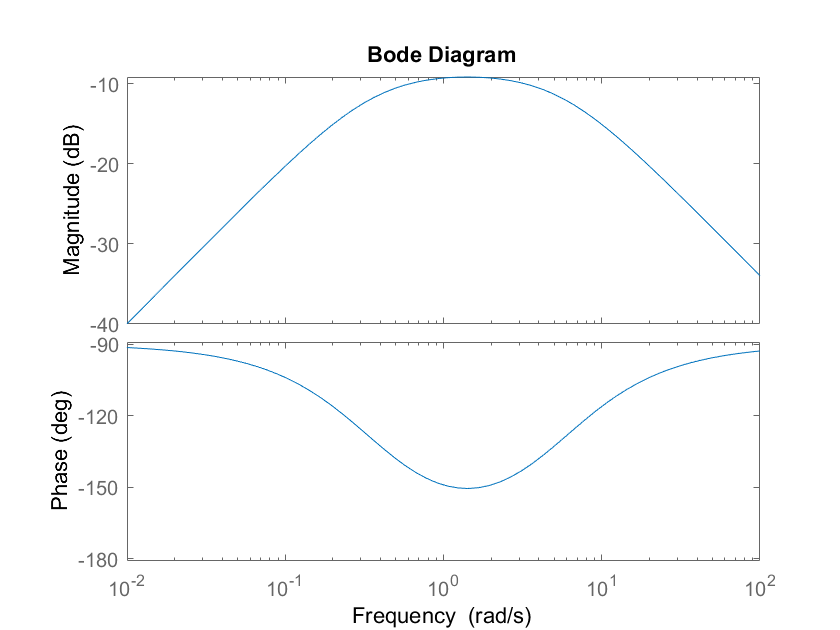

bode(G2)

% No, although they are the same in the plot
% there are some difference in the expression of transfer function

